1. Загрузите данные **ex5data1.mat **из файла.

load('ex6data1.mat');

2. Постройте график для загруженного набора данных: по осям - переменные X1, X2, а точки, принадлежащие различным классам должны быть обозначены различными маркерами.

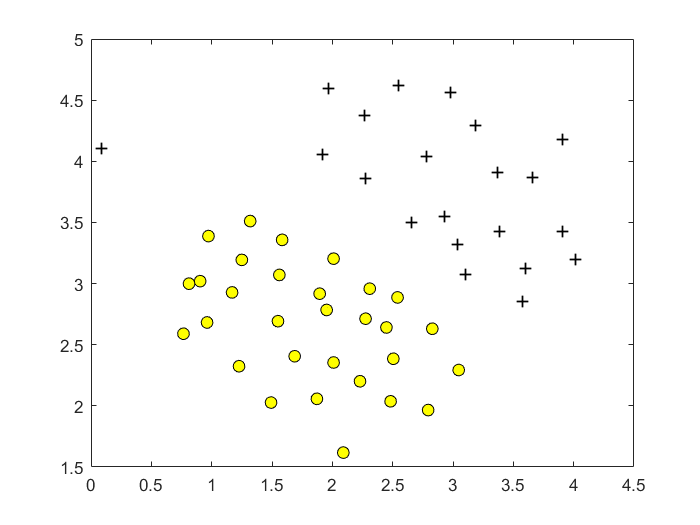

plotData(X, y);

3. Обучите классификатор с помощью библиотечной реализации SVM с линейным ядром на данном наборе.

4. Постройте разделяющую прямую для классификаторов с различными параметрами C = 1, C = 100 (совместно с графиком из пункта 2). Объясните различия в полученных прямых?

C = 1;
model = svmTrain(X, y, C, @linearKernel, 1e-3, 20);


Training .................................................................. Done! 



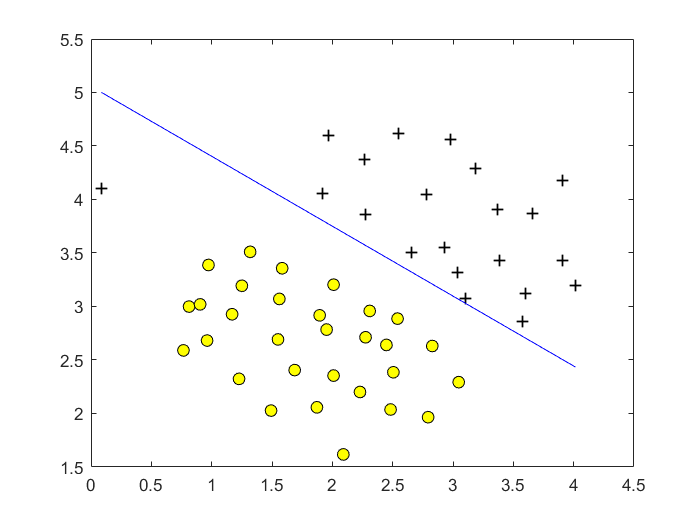

visualizeBoundaryLinear(X, y, model);

C = 100;
model = svmTrain(X, y, C, @linearKernel, 1e-3, 20);


Training ......................................................................
...............................................................................
...............................................................................
...............................................................................
...............................................................................
....................................... Done! 



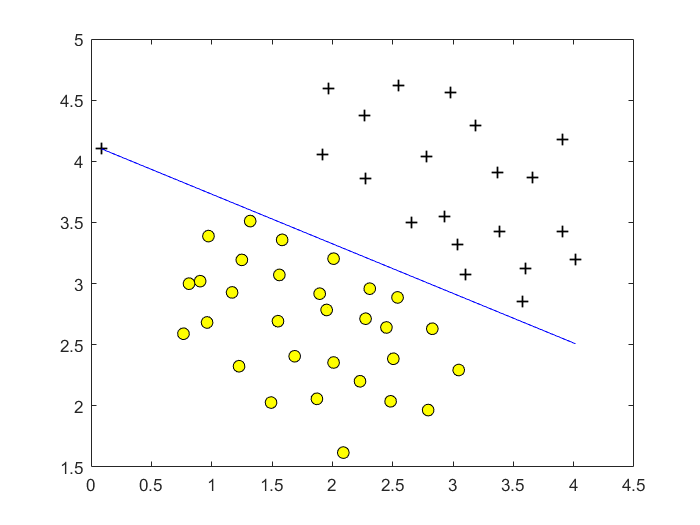

visualizeBoundaryLinear(X, y, model);

При большем C линия разделила все примеры, менее чувствительна к примерам не похожим на общий тренд. При меньшем C линия более похожая на естественную.

5. Реализуйте функцию вычисления Гауссового ядра для алгоритма SVM.

6. Загрузите данные **ex5data2.mat **из файла.

load('ex6data2.mat');

7. Обработайте данные с помощью функции Гауссового ядра.

8. Обучите классификатор SVM.

9. Визуализируйте данные вместе с разделяющей кривой (аналогично пункту 4).

C = 1; sigma = 0.1;
model= svmTrain(X, y, C, @(x1, x2) gaussianKernel(x1, x2, sigma)); 


Training ......................................................................
...............................................................................
...............................................................................
...............................................................................
...............................................................................
...............................................................................
...............................................................................
...............................................................................
. Done! 



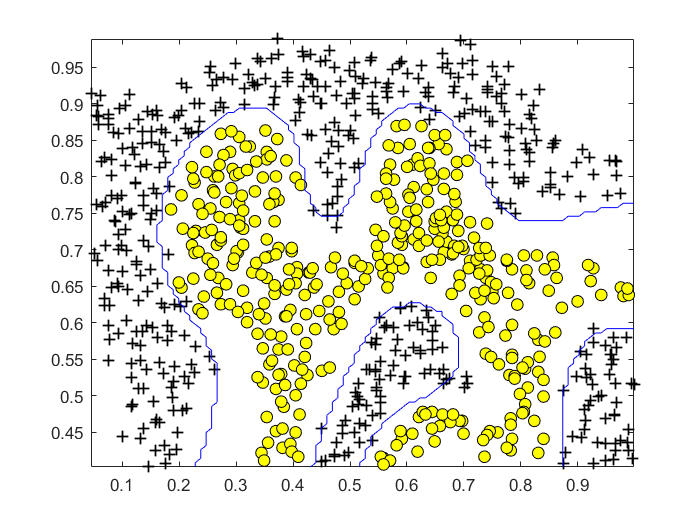

visualizeBoundary(X, y, model);

10. Загрузите данные **ex5data3.mat **из файла.

load('ex6data3.mat');

11. Вычислите параметры классификатора SVM на обучающей выборке, а также подберите параметры C и σ2 на валидационной выборке.

12. Визуализируйте данные вместе с разделяющей кривой (аналогично пункту 4).

% Try different SVM Parameters here
[C, sigma] = dataset3Params(X, y, Xval, yval)


Training ......... Done! 


Training ....................................... Done! 


Training ................................................. Done! 


Training .................................... Done! 


Training ............................................................ Done! 


Training ..................................... Done! 


Training ........................................... Done! 


Training .......................................................... Done! 


Training ......... Done! 


Training ............................................................ Done! 


Training ............................................................... Done! 


Training .............................................................. Done! 


Training ....................................... Done! 


Training ...................................................... Done! 


Training .............................................. Done! 


Training ....................................... D

C = 1

sigma = 0.1000


% Train the SVM
model = svmTrain(X, y, C, @(x1, x2)gaussianKernel(x1, x2, sigma));


Training ......................................................................
...............................................................................
...............................................................................
................................ Done! 



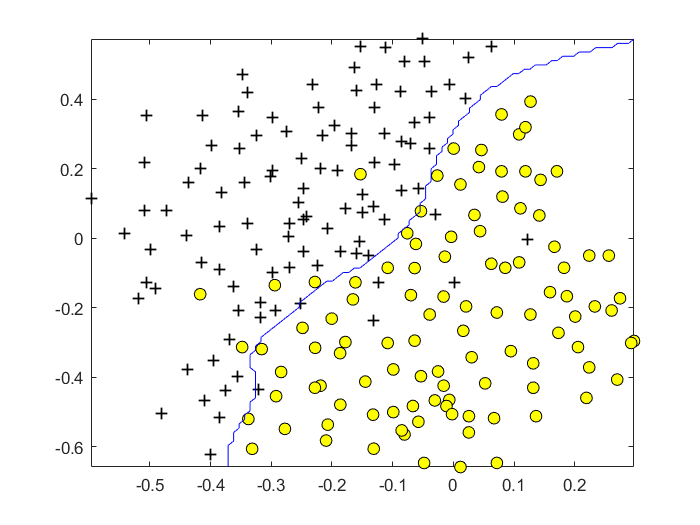

visualizeBoundary(X, y, model);

13. Загрузите данные **spamTrain.mat **из файла.

load('spamTrain.mat');

14. Обучите классификатор SVM.

C = 0.1;
model = svmTrain(X, y, C, @linearKernel);


Training ......................................................................
...............................................................................
...............................................................................
........................................ Done! 




p = svmPredict(model, X);
fprintf('Training Accuracy: %f\n', mean(double(p == y)) * 100);

Training Accuracy: 99.825000


15. Загрузите данные **spamTest.mat **из файла.

load('spamTest.mat');


Xtest =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1     0     0     1     0     0     0     0     

p = svmPredict(model, Xtest);
fprintf('Test Accuracy: %f\n', mean(double(p == ytest)) * 100);

Test Accuracy: 98.900000


[C, sigma] = dataset3Params(X, y, Xval, yval)

Undefined function or variable 'Xval'.

17. Реализуйте функцию предобработки текста письма.

18. Загрузите коды слов из словаря **vocab.txt**.

19. Реализуйте функцию замены слов в тексте письма после предобработки на их соответствующие коды.

20. Реализуйте функцию преобразования текста письма в вектор признаков (в таком же формате как в файлах **spamTrain.mat** и **spamTest.mat**).

test = emailFeatures(processEmail(readFile('emailSample1.txt')))


==== Processed Email ====

do you want to make dollarnumb or more per week if you ar a motiv and qualifi 
individu i will person demonstr to you a system that will make you dollarnumb 
number per week or more thi is not mlm call our number hour pre record number 
to get the detail number number number i need peopl who want to make seriou 
monei make the call and get the fact invest number minut in yourself now 
number number number look forward to your call and i will introduc you to 
peopl like yourself who ar current make dollarnumb number plu per week number 
number number numberljgvnumb numberleannumberlrmsnumb 
numberwxhonumberqiytnumb numberrjuvnumberhqcfnumb numbereidbnumberdmtvlnumb 



test =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


p = svmPredict(model, test)

p = 1